# E5

# Processat Morfològic d’imatges

I = imread('Bracket1.tif');
BW = I < 128;

#### Dilatació

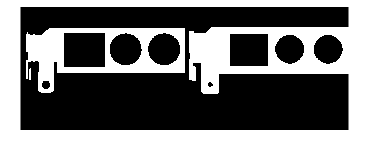

SE = ones(11,11);
BWD = imdilate(BW,SE);
montage({BW,BWD});

#### Erosió

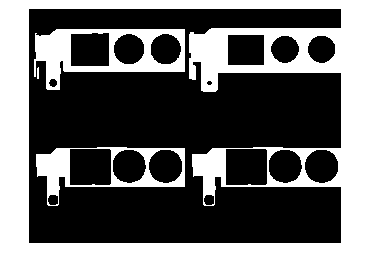

SE = ones(11,11);
BWE = imerode(BW,SE);
% test: erosió és una dilatació del background
BWT = not(imdilate(not(BW),SE));
montage({BW,BWD,BWE,BWT});

#### Residus

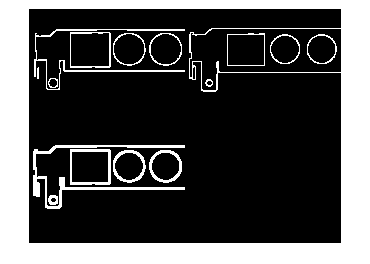

RI = BW & not(BWE);
RE = BWD & not(BW);
RD = BWD & not(BWE);
montage({RI,RE,RD});

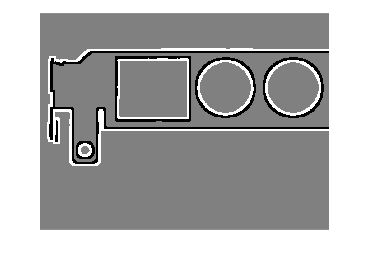


L = double(RE)-double(RI);  % Laplacià morfològic
imshow(L,[]);

#### Transformada de distància

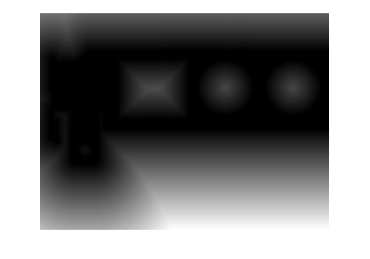

TD = bwdist(BW,'euclidean');
imshow(TD,[]);

#### Recontrucció

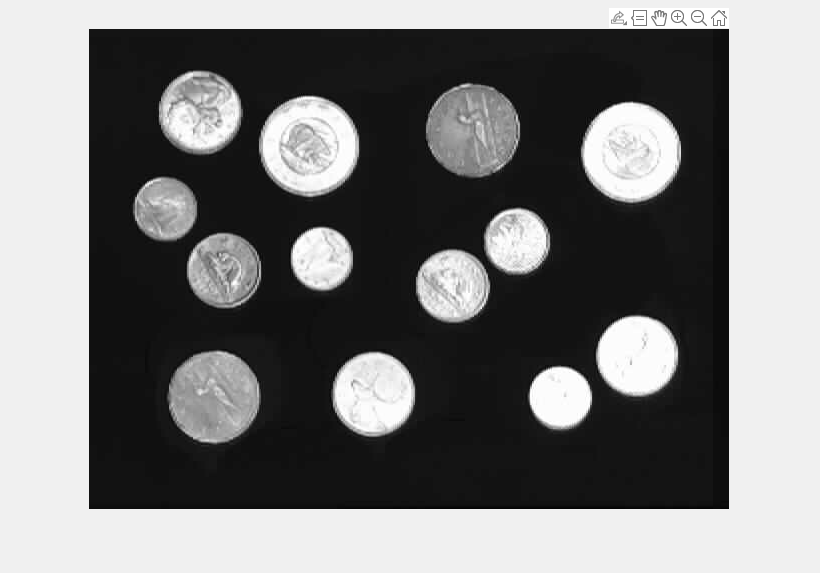

I = imread('money.tif');
BW = I > 128;
SE = ones(5,5);
imshow(I,[]);
[x y] = getpts;

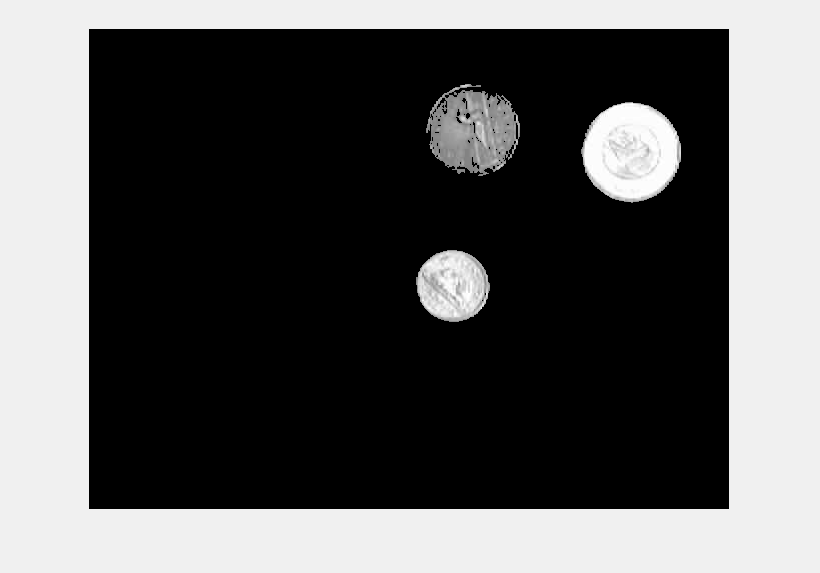

MARK = false(size(BW));
for i = 1:size(x)
    MARK(uint16(y(i)),uint16(x(i))) = 1;
end
REC = imreconstruct(MARK,BW);
imshow(uint8(REC).*I,[]);

#### Close

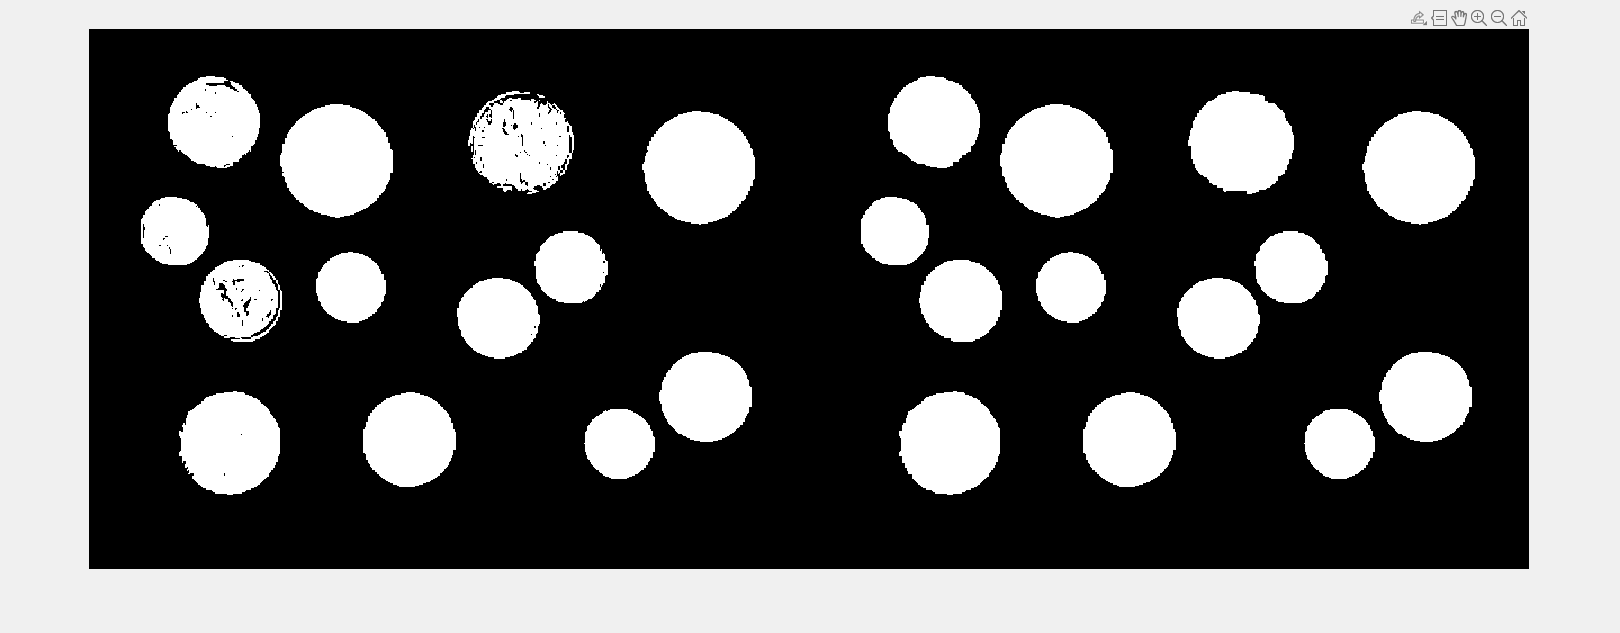

I = imread('money.tif');
BW = I > 128;
SE = ones(7,7);
BWC = imdilate(BW,SE);
BWC = imerode(BWC,SE);
montage({BW,BWC});

#### Exercici 1

Eliminar objectes de les vores

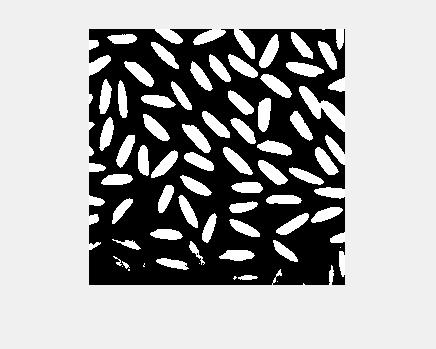

I = imread('arros.tif');
BW = I > 128;
SE = ones(7,7);
imshow(BW,[]);

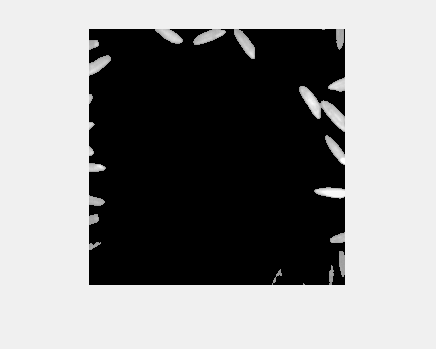

MARK = false(size(BW));
MARK(1,:) = 1;
MARK(end,:) = 1;
MARK(:,1) = 1;
MARK(:,end) = 1;

REC = imreconstruct(MARK,BW);
imshow(uint8(REC).*I,[]);

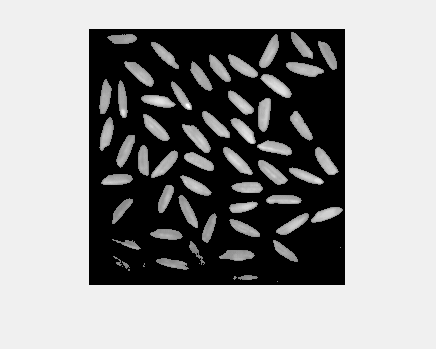

BWM = BW & not(REC);
imshow(uint8(BWM).*I,[]);

#### Exercici 2

Comptar les dents d'una roda dentada

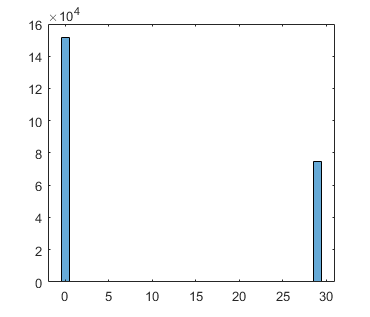

I = rgb2gray(imread('Wheel.bmp'));
histogram(I);

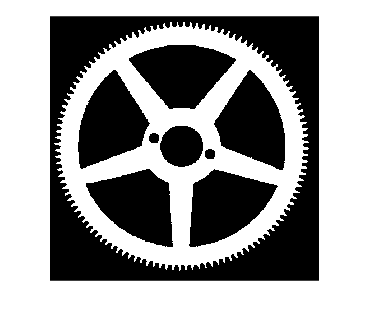

BW = I > 20;
imshow(BW);

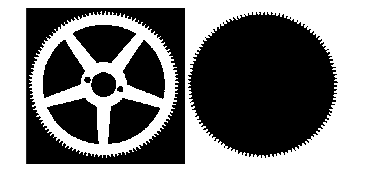


MARK = false(size(BW));
MARK(1,:) = 1;
MARK(end,:) = 1;
MARK(:,1) = 1;
MARK(:,end) = 1;

REC = imreconstruct(MARK,not(BW));
montage({BW,REC})

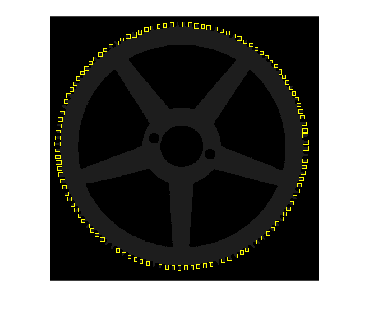

REC = not(REC);
O = imopen(REC,ones(10,10));
BWS = REC & not(O);

% region props
RP = regionprops('table',BWS,'BoundingBox','Area');
RGB = insertShape(I,'rectangle',RP.BoundingBox);
imshow(RGB);

#### Exercici 3

Entrar a un laberint

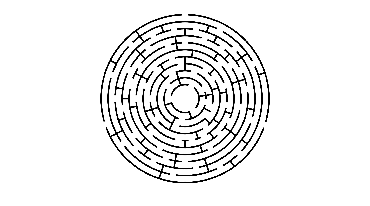

I = rgb2gray(imread('Laberint.png'));
imshow(I);

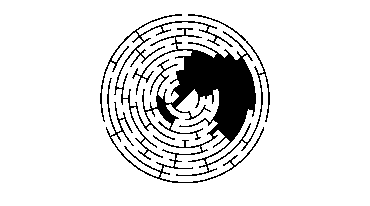

BW = I > 128;
MARK = false(size(BW));
DT = zeros(size(BW));
MARK(1,1) = 1; % posició inicial de partida
SE = [0 1 0; 1 1 1; 0 1 0];

[f c] = size(BW);
centre = [floor(f/2) floor(c/2)];
fi = false;
while not(fi)
    MARK = imdilate(MARK,SE) & BW;
    DT = DT + MARK;
    %imshow(MARK);
    %drawnow;
    if MARK(centre(1),centre(2))
        fi = true;
    end
end
imshow(MARK);

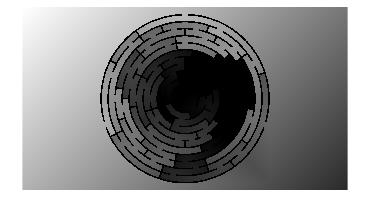

imshow(DT,[]);